# Exercise 4.2 - Effort-Based Control using the Dynamic Model 

In this exercise, you will implement a **joint-space PD controller** with **gravity and dynamic compensation** for a UR manipulator. The goal is to drive all joints of the robot smoothly toward a desired configuration (`qd`) while respecting joint torque limits.

## Task

Your controller will operate in the **effort control mode**, meaning it will directly send **joint torques** to the simulated robot.

At each control step, you will:

- Read the current joint positions and velocities from the simulator.

- Compute the dynamic model of the robot (mass matrix, Coriolis/centrifugal terms, and gravity torques).

- Calculate the control torques using a PD law in the joint space.

- Apply **torque saturation** to stay within physical actuator limits.

- Send the computed torques back to the simulator.

## Import the Robot

Instead of using the standard library of MATLAB, for this exercise import the robot using the raw URDF file. 

- importrobot(["robotics/Ros/src/ur5e.urdf"]);

Hint: Remember to set the gravity and data structure. 

## Functions to Interface the Simulation

Use the following helper functions to communicate with the simulator:

- `[q, q_dot, ~] = GetJointValues('All')`Reads the current **joint positions** (`q`, in radians) and **joint velocities** (`q_dot`, in radians/second`) from the ROS network.Both are returned as 6×1 column vectors.

- `SendJointTorques(tau_sat)`Sends a 6×1 vector of torques (in **Nm**) to the robot joints.The vector must respect the robot’s torque limits.

## **Controller Structure**

The implemented PD controller with dynamics compensation has the following general form:


$$\tau =M\left(q\right)\cdot \left(\textrm{Kp}\cdot e+\textrm{Kd}\cdot \dot{e} \right)+C\left(q,\dot{q} \right)\cdot \;\dot{q} +g\left(q\right)$$


with the errors: 


$$e=q_{\textrm{desired}} -q$$


$\dot{e} =\dot{q_{\textrm{desired}} } -\dot{q}$ in our case $\dot{q_{\textrm{desired}} } =0$

## Torque Saturation

Real robots cannot produce infinite torque.

To avoid unrealistic commands, we apply **torque saturation** using element-wise limits. 


$$\tau_{\textrm{sat}} \le \tau_{\max }$$


Use the figure below to construct the torque limit vector specific to your robot. 

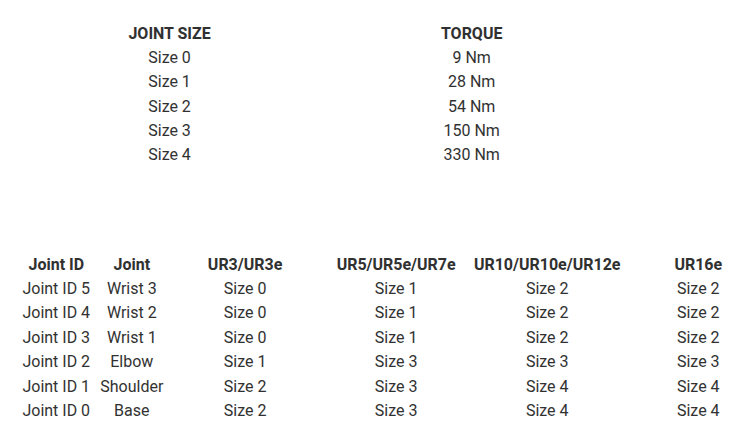

## Other properties: 

This controller needs to be fast. Try to achieve a frequency of 50 - 100 Hz for a stable simulation. 

## Optional Visualization: 

You can store the joint states, speeds and torques and visualize them using the function: 

- plotTrajectory(qstorage, qdstorage, tau_storage)

You can visualize the Kineo Static Duality as a manipulability ellipsoid using the function: 

-  JointStatesToRviz(q, ur_model, [], 'Ellipsoid', true, EllipsoidResolution', 15, 'EllipsoidDuality', 'Force', 'SendJointStates', false);

**IMPORTANT: **The computation of the ellipsoid is relatively expensive, therefore to maintain a high control frequency only plot the Ellipsoid every N loops. If N is too low the controller will fail!

Start the Simulation by running: 

%StartTutorialApplication('Simulation','Controller', 'Effort', 'Model','ur5e');
%If you use ROS on a native Ubuntu system use: 
StartTutorialApplication('Simulation','Controller', 'Effort', 'Model','ur5e', 'Docker', false);

To see the path of the end effector you can run: 

%StartTutorialApplication('Trajectory'); 
%If you use ROS on a native Ubuntu system use: 
StartTutorialApplication('Trajectory', 'Docker', false);


    %================== User-tunable parameters ==================%
    qd1      = zeros(6,1);                     % target configuration (rad)
    qd2     = [0,-pi/2,0,-pi/2,pi/5,pi/7]'; 
    qd3 = [pi/2,pi/4,pi/5,-pi/2,0,pi]';
    % Base gains (per joint) — tune as needed
    Kp = diag([90 90 70 45 30 18]);           % proportional
    Kd = 1.5*diag([18 18 12  8  6  3.6]);         % derivative

    tau_lim = [150,150,150,28,28,28]';
    
    dt = 0.01;                                % s (100 Hz)
    g  = [0 0 -9.81];                         % gravity in base frame

    % Load UR3e model
    model='ur5e'; 
    robot = importrobot(["robotics/Ros/src/ur5e.urdf"], DataFormat="column");
     robot = loadrobot("universalUR5e", DataFormat="column", Gravity=g);

    robot.Gravity = g; 
    % robot = loadrobot("universalUR5e", DataFormat="column", Gravity=g);

    r  = rateControl(1/dt);
    

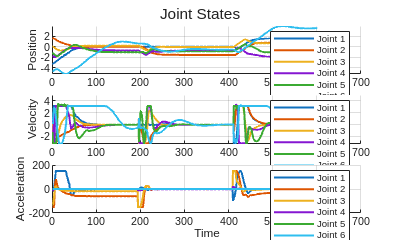

    t0=tic;
    count=0;

    qstorage = []; 
    qdstorage = []; 
    tau_storage = []; 

    try
        while toc(t0)<15
            % 1) Read current state
            [q, q_dot, ~] = GetJointValues('All');   % each 6x1
            q = q(:); q_dot = q_dot(:);
            if toc(t0)<5
                qd=qd1;
            elseif toc(t0)<10
                qd=qd2; 
            else

                qd=qd3;
            end
            
            % if(mod(count,20)==0)
            %     JointStatesToRviz(q, model, [],'Ellipsoid',true, 'EllipsoidResolution',15,'EllipsoidDuality','Force','SendJointStates',false);
            % end
            count=count+1; 
            % 2) Dynamics
            M = massMatrix(robot, q);
            h = velocityProduct(robot, q, q_dot);    % C(q,dq)*dq
            G = gravityTorque(robot, q);

            % 3) Errors
            e  = qd - q;
            ed = -q_dot;

            % 4) Control input 
            v = Kp*e + Kd*ed ;


            % 5) Full torque
            tau = (M*v + h + G);

            % 6) Saturation handling
            tau_sat = min(max(tau, -tau_lim), tau_lim);

            % 7) Send torques
            SendJointTorques(tau_sat);
            
            %Store states
            qstorage = [qstorage, q]; 
            qdstorage = [qdstorage, q_dot]; 
            tau_storage=[tau_storage, tau_sat];


            waitfor(r);
        end
    catch ME
        warning('[reachZeroUREffort] Error: %s', ME.message);
    end

    % Safe stop
    try
        SendJointTorques(zeros(6,1)); 
    end

    %plot trajectory
plotTrajectory(qstorage,qdstorage,tau_storage)